**Collaborated with Bing Chen Liu**

**Reviewed Okun's cosine window on Github to understand how to apply/normalize one**

1. Compute two spectra. For this problem set, please generate a 10,000 element data set with Gaussian white noise. Use your white noise to generate a second data set that is the time integral of the first. Hint: use cumsum in MATLAB; note you’ll need to specify the sample interval.) 

Now compute and plot spectra for the white noise and time-integrated data sets by breaking the data up into segments with 50% overlaps, with no windowing. (You can do this by reshaping your data vector as a 500×20 matrix, which will give you 20 segments, each 500 points long, and a 500×19 matrix containing the 50% overlaps.). Make sure you plot the spectrum with correct units and that you verify normalization using Parseval’s theorem. 

- **dt = 10 minutes**

Data = CreateData(10000,1,1,10); %Create data
SegmentedData = SegmentData(Data,500); %Segment data

[spectra, frqvector,df,fn] = Spectra2(Data.WhiteNoise,10,'none'); % Check parseval
variance_w=nanmean(detrend(Data.WhiteNoise,1).^2)

variance_w = 1.0200

sum_spec=sum(spectra)*df

sum_spec = 1.0200

sum_spec / variance_w

ans = 1.0000

% %good!!
[spectra, frqvector,df] = Spectra2(Data.TimeInt,10,'none'); % Check parseval
variance_T=nanmean(detrend(Data.TimeInt,1).^2)

variance_T = 1.1575e+05

sum_spec=sum(spectra)*df

sum_spec = 1.1575e+05

sum_spec / variance_T

ans = 1.0000

% %good!!

[spectra, frqvector,df,fn] = Spectra2(SegmentedData.WhiteNoise,10,'none'); % Check parseval
data = detrend(Data.WhiteNoise);
variance_sw=nanmean(data.^2)

variance_sw = 1.0200

sum_spec=sum(spectra)*df

sum_spec = 1.0176

sum_spec / variance_sw

ans = 0.9977

%good!

[spectra, frqvector,df] = Spectra2(SegmentedData.TimeInt,10,'none'); % Check parseval
data = detrend(Data.TimeInt);
variance_sT=nanmean(data.^2)

variance_sT = 1.1575e+05

sum_spec=sum(spectra)*df

sum_spec = 3.1995e+03

sum_spec / variance_sT %something is very wrong with my normalization here. 

ans = 0.0276

% I cannot figure out how to get this to equal 1

figure(1)
clf
TL = SpectraPlots(2,1);

nexttile
[y, f_vector] = Spectra2(SegmentedData.WhiteNoise,10,'none');
loglog(f_vector,y)
title([char(Data.Names(1))])
legend('Data Spectrum','Segmented Data Spectrum')

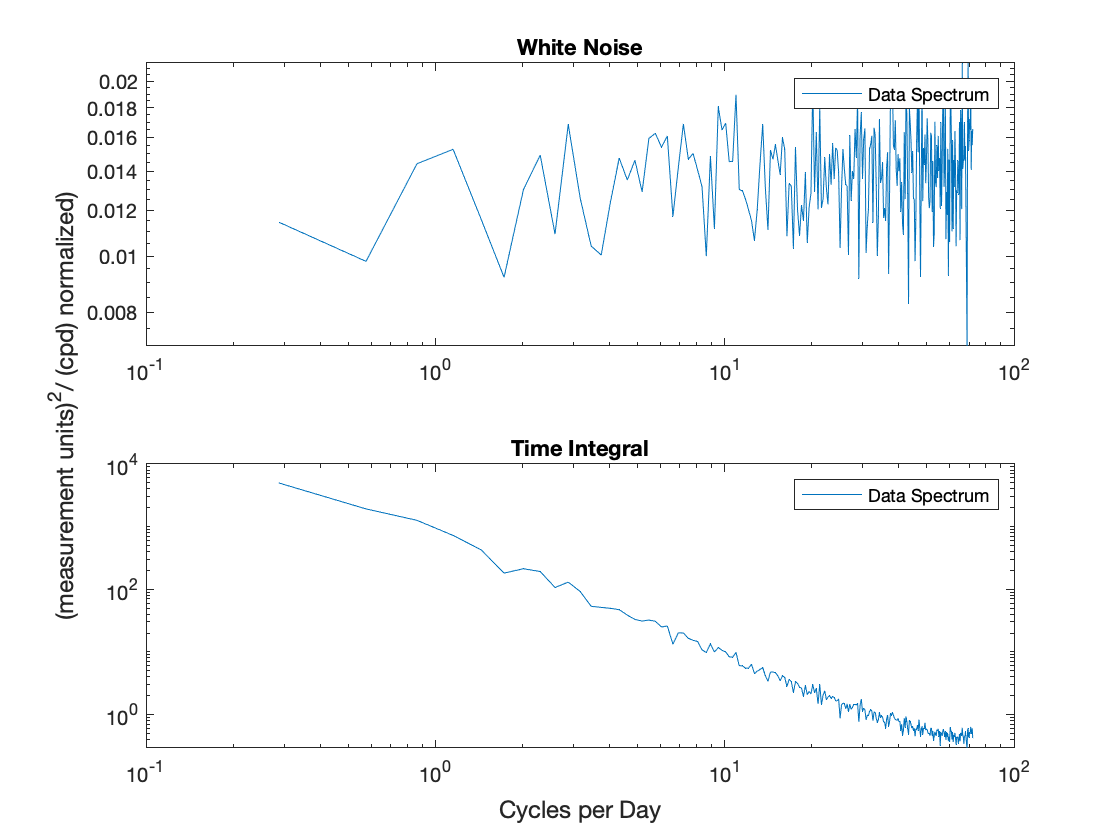


nexttile
[y, f_vector] = Spectra2(SegmentedData.TimeInt,10,'none');
loglog(f_vector,y)
title([char(Data.Names(2))])
legend('Data Spectrum','Segmented Data Spectrum')

2. Analytical spectra. Given that you know the variance of your white-noise time series, overplot the expected analytical spectrum (hint: use Parseval’s theorem). Then, for the time-integrated spectrum, use the relationship we learned for Fourier coefficients of derivatives and integrals to overplot the analytical spectrum for the spectrum of the time-integral. 

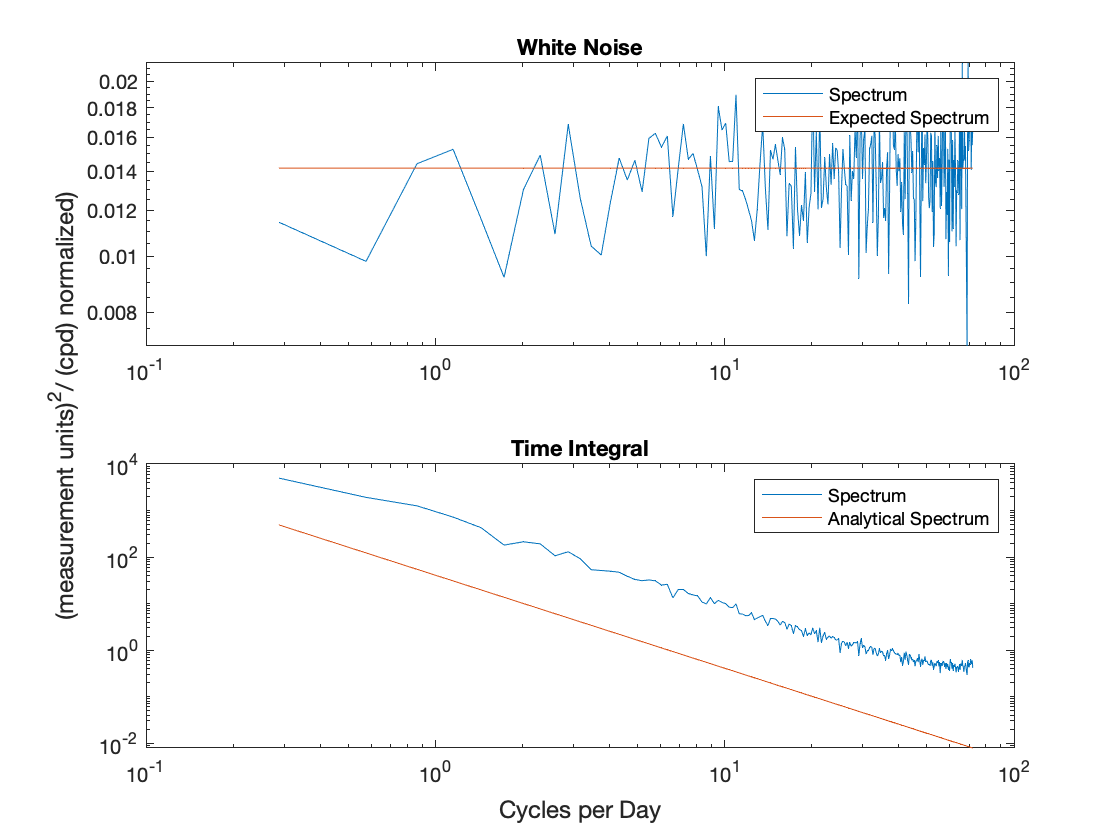

figure(2)
clf
TL = SpectraPlots(2,1);

nexttile
[y, f_vector,~,fn] = Spectra2(SegmentedData.WhiteNoise,10,'none');
loglog(f_vector,y)
hold on
est = variance_w/fn;
est_y = ones(length(y),1) * est;
loglog(f_vector,est_y) 
title([char(Data.Names(1))])
legend('Spectrum','Expected Spectrum')
nexttile
[y, f_vector,~,fn] = Spectra2(SegmentedData.TimeInt,10,'none');
loglog(f_vector,y)
hold on
est = variance_sT/fn;
est_y = ones(length(y),1) .* est ./ (2*pi*f_vector.').^2; %This is not quite right
%might be related to the issue with variance above.
loglog(f_vector,est_y) 
title([char(Data.Names(2))])
legend('Spectrum','Analytical Spectrum')

3. Error bars. Following the procedure that you’ve used before, add error bars to your spectra. Justify how you computed them.

- Degrees of freedom was found from the lecture slide. Boxcar, overlapping segments have DoF = (4/3) * # of segments.

- Next, I scaled the chi^2 estimates according to the frq on the spectrum that I wanted to display them.

- err_low = nu/chi2inv(1-.05/2,nu) *spectra(frq);

- err_high= nu/chi2inv(.05/2,nu) *spectra(frq) ;

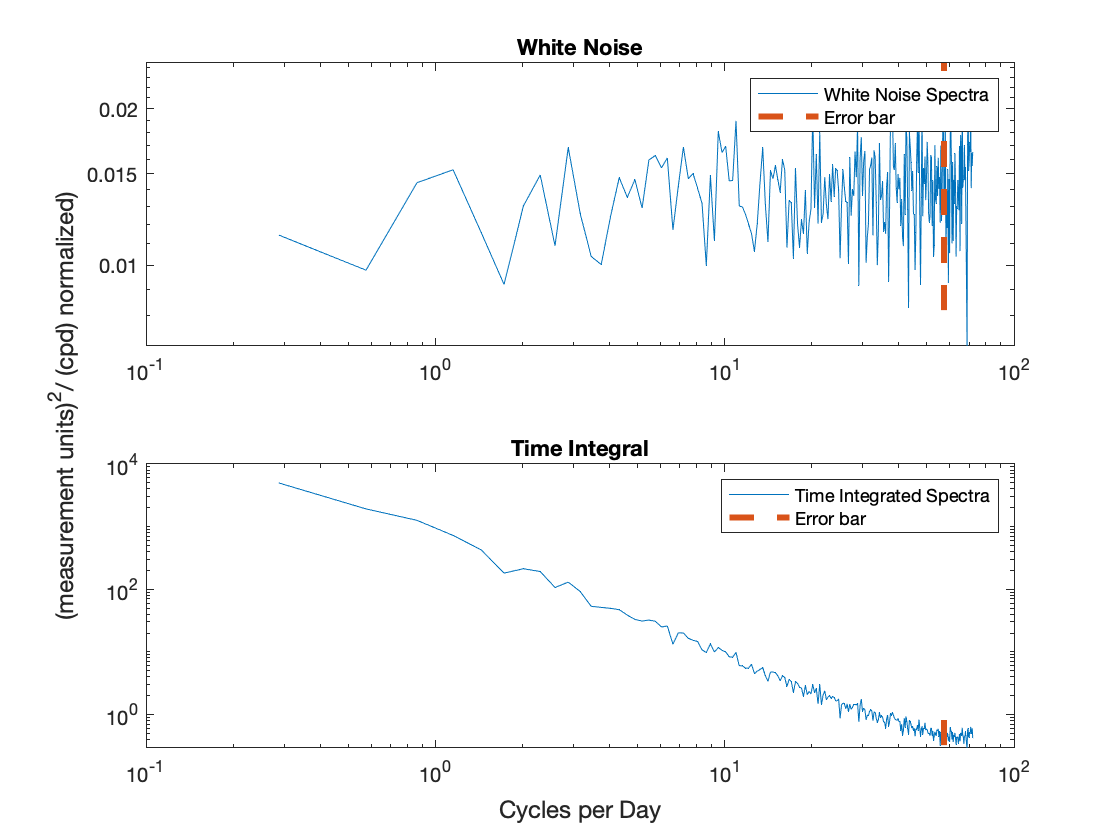

figure(2)
clf
TL = SpectraPlots(2,1);

nexttile
[y, f_vector] = Spectra2(SegmentedData.WhiteNoise,10,'none');
loglog(f_vector,y)
hold on
[x, errorbar] = ErrorBar(f_vector(200),f_vector,y,(4/3)*20); %(4/3)*20 independent samples
loglog(x,errorbar,'LineWidth',3,'LineStyle','--')
title([char(Data.Names(1))])
legend('White Noise Spectra','Error bar')


nexttile
[y, f_vector] = Spectra2(SegmentedData.TimeInt,10,'none');
loglog(f_vector,y)
hold on
[x, errorbar] = ErrorBar(f_vector(200),f_vector,y,(4/3)*20); 
loglog(x,errorbar,'LineWidth',3,'LineStyle','--')
title([char(Data.Names(2))])
legend('Time Integrated Spectra','Error bar')

4. Use Monte Carlo simulation to verify the χ2 error bars. To check the error bars, you’ll want to generate multiple ensembles of data and compute spectra for each of them. I suggest using 200 matrices that are 500×20 elements each. Compute spectra for each of them. This will provide you with 200 independent realizations of the spectrum, and you can use these 200 values to study the range of possible spectra that you could obtain from white noise. Examine the pdf of your 200 values. (Because the statistics of Gaussian white noise are the same at all frequencies, you can merge all the frequencies to produce a larger ensemble.)** Is the pdf consistent with your expectations for a variable with a χ2 distribution? **

- **Yes, the PDF is consistent with a chi^2 variable. PDF Histogram is below.**

Now, for each frequency, sort the 200 realizations of the pdf by size (e.g. using the “sort” command in Matlab. Since you are looking for the 95% confidence range, you’ll want to find the limits that exclude the lowest 2.5% and the highest 2.5% of your data—presumably the 6th and 195th points in each sorted set of pdfs.) **What is the ratio of the upper limit to the lower limit? Are the error bars derived using the Monte Carlo process consistent with those from question 1? **

- **The MC method has a smaller ratio than that from question one. They are fairly consistent however, as they are within the same order of magnitude. All the ratios are below.**

Optional: You can also check your results using the red spectrum. One difference is that the white spectrum exhibits the same behavior at all frequencies allowing you to average in frequency. That isn’t possible with the red spectrum, though you can average the ratio between the upper and lower bounds of the uncertainty estimate.

MC = CreateData(500,20,200,10);
MC.WhiteNoise = detrend(MC.WhiteNoise,1);

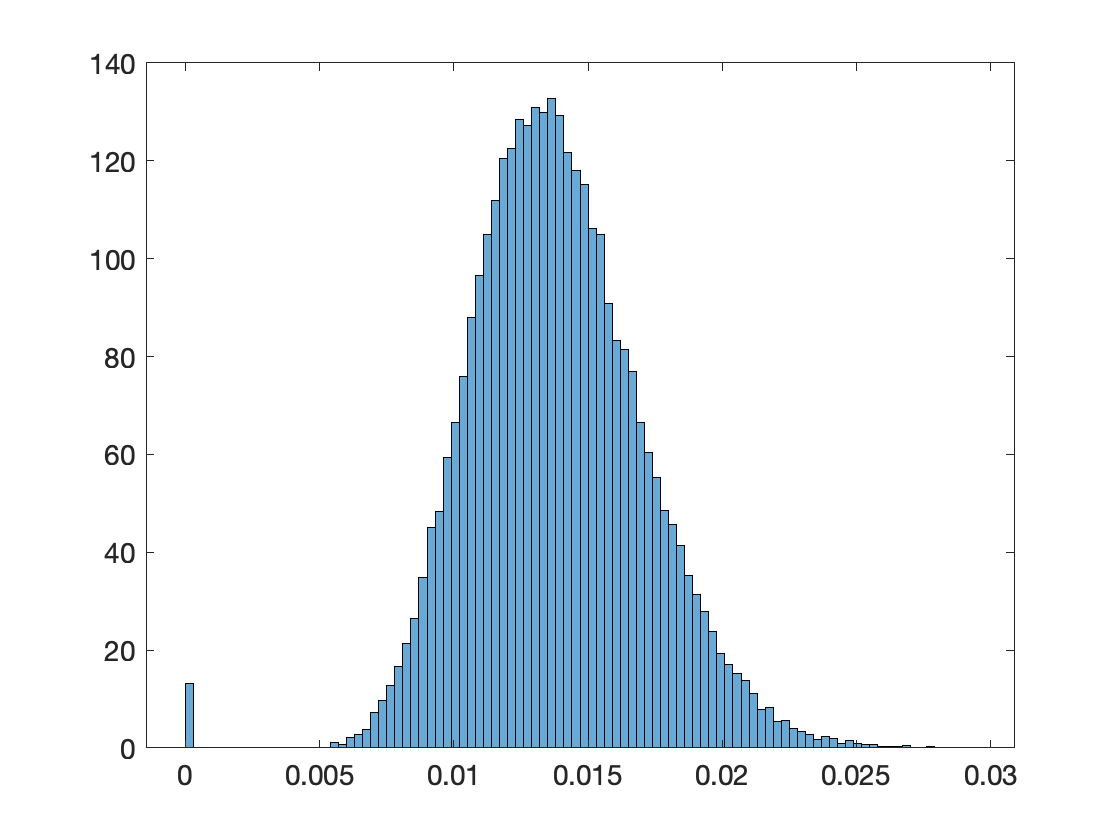

spectras = nan(251,1,200);
for i = 1:length(MC.WhiteNoise(1,1,:))
    spectras(:,:,i) = Spectra2(MC.WhiteNoise(:,:,i),10,'None');
end

Spec1 = squeeze(spectras);
frq2analyze1 = Spec(230,:);

figure(3)
clf
histogram(Spec1(:,:),'Normalization',"pdf")


S = sort(frq2analyze);
Ratio1 = S(195)/S(6)

Ratio1 = 2.8191


[y, f_vector] = Spectra2(SegmentedData.WhiteNoise,10,'none');
[x, errorbar] = ErrorBar(f_vector(200),f_vector,y,(4/3)*20);
Ratio2 = errorbar(end)/errorbar(1)

Ratio2 = 2.9848

5. Monte Carlo process for a Hanning window. Repeat the Monte Carlo process to estimate the χ2 error bars for data using a Hanning window for each segment and 50% overlap. **Are the results consistent with what you would expect based on the discussion in class? **

- **These results are expected based on the discussion that the Hanning window will produce a narrower PDF because it has more degrees of freedom.**

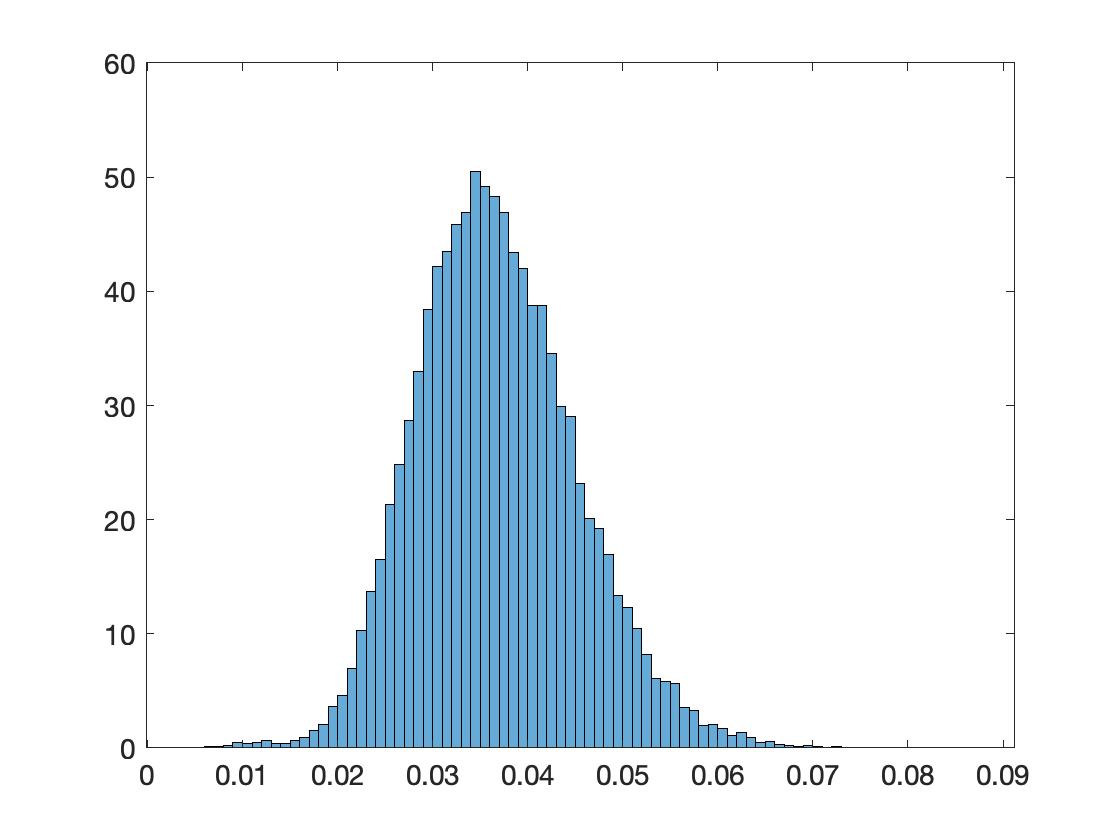

spectras = nan(251,1,200);
for i = 1:length(MC.WhiteNoise(1,1,:))
    spectras(:,:,i) = Spectra2(MC.WhiteNoise(:,:,i),10,'Hanning');
end

Spec2 = squeeze(spectras);
frq2analyze2 = Spec2(230,:);

figure(3)
clf
histogram(Spec2(:,:),'Normalization',"pdf")


S = sort(frq2analyze);
Ratio1 = S(195)/S(6)

Ratio1 = 2.8191


[y, f_vector] = Spectra2(SegmentedData.WhiteNoise,10,'none');
[x, errorbar] = ErrorBar(f_vector(200),f_vector,y,(4/3)*20);
Ratio2 = errorbar(end)/errorbar(1)

Ratio2 = 2.9848

6. Monte Carlo process for a cosine window. Finally, repeat the Monte Carlo process for a cosine window (cos(πt/T ), where −T /2 < t < T /2). How many effective degrees of freedom do you obtain for 50% overlap.

- Boxcar window: (4/3)DoF / Segment: (4/3)*39 = 52 DoF.

- Hanning window 1.90 / Segment: 1.9*39 = 74 DoF

- Unsure of the Cosine Window, however it appears to have more DoF than both of these other methods, maybe because I made a mistake creating the window

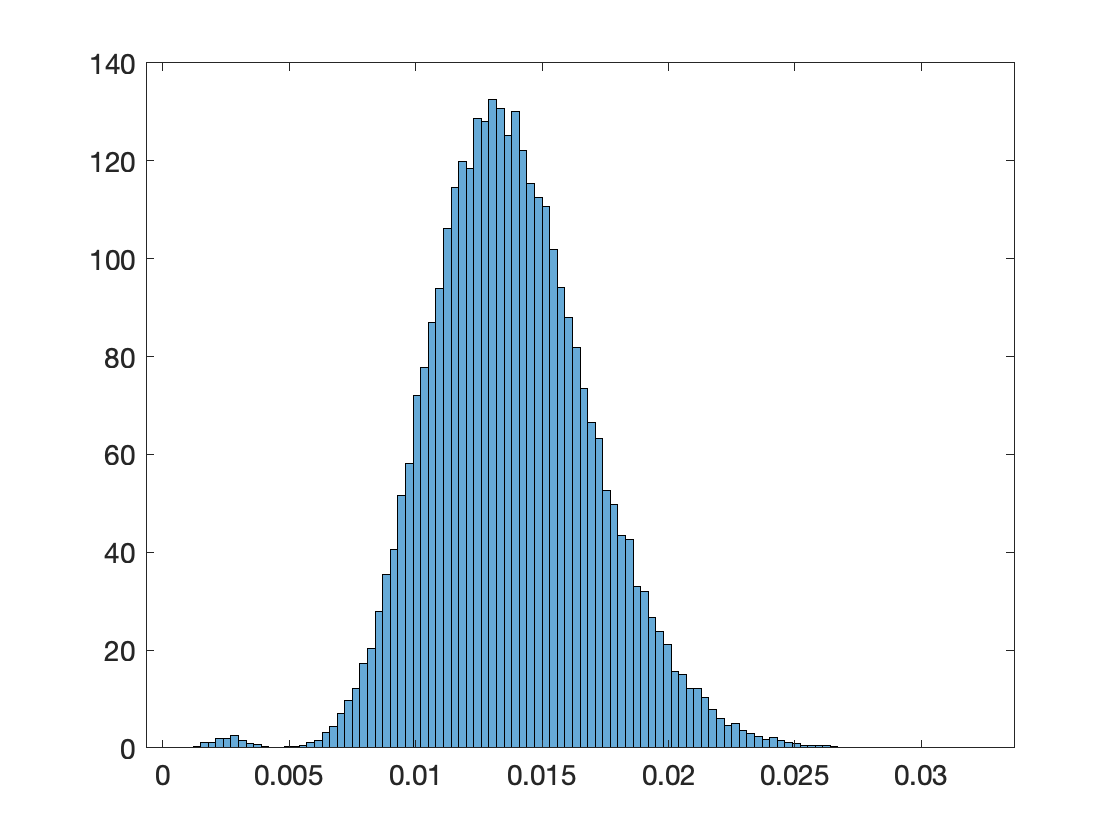

spectras = nan(251,1,200);
for i = 1:length(MC.WhiteNoise(1,1,:))
    spectras(:,:,i) = Spectra2(MC.WhiteNoise(:,:,i),10,'Cosine');
end

Spec3 = squeeze(spectras);
frq2analyze3 = Spec3(230,:);

figure(3)
clf
histogram(Spec3(:,:),'Normalization',"pdf")


S = sort(frq2analyze);
Ratio1 = S(195)/S(6)

Ratio1 = 2.8191


[y, f_vector] = Spectra2(SegmentedData.WhiteNoise,10,'none');
[x, errorbar] = ErrorBar(f_vector(200),f_vector,y,(4/3)*20);
Ratio2 = errorbar(end)/errorbar(1)

Ratio2 = 2.9848

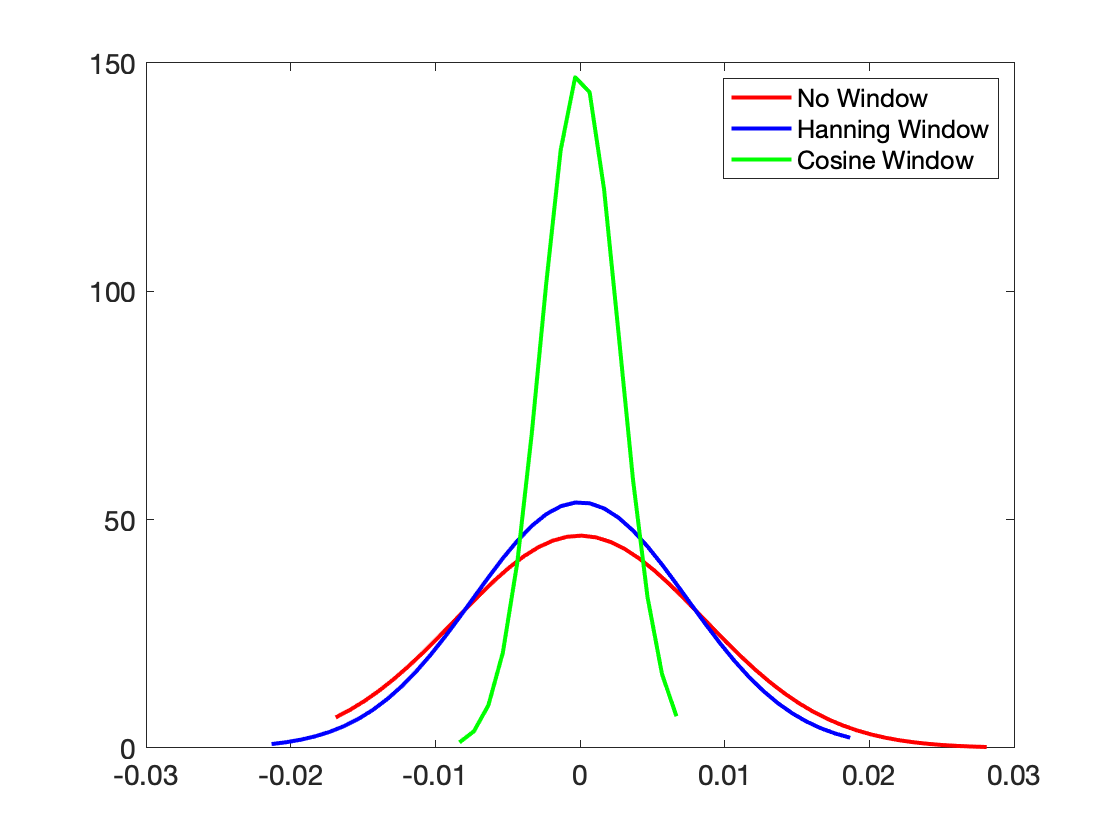

figure(4)
clf
frq2analyze1 = detrend(frq2analyze1);
x = (min(mm):.001:max(mm));
norm = normpdf(x,mean(mm),std(mm));
plot(x,norm,"LineWidth",2,'Color','red')
hold on
frq2analyze2 = detrend(frq2analyze2);
x = (min(frq2analyze2):.001:max(frq2analyze2));
norm = normpdf(x,mean(frq2analyze2),std(frq2analyze2));
plot(x,norm,"LineWidth",2,'Color','blue')

frq2analyze3 = detrend(frq2analyze3);
x = (min(frq2analyze3):.001:max(frq2analyze3));
norm = normpdf(x,mean(frq2analyze3),std(frq2analyze3));
plot(x,norm,"LineWidth",2,'Color','green')

legend('No Window','Hanning Window','Cosine Window')

7. Bonus. Derive the analytic solution for a cosine window with 50% overlap. Does it agree with your numerical results?